# APMA 2501 - Programming in R & MATLAB: MATLAB Unit 1

## Introduction

Why computer programming?

- To calculate a result from a complicated algorithm

- To analyze limited measurement data in order to estimate the state of a system

- To simulate, e.g., natural phenomena or behavior of engineered systems

- To control a system to behave in a particular manner

- To automate a tedious or time-consuming process

- To design new products, materials, or techniques

- To efficiently carry out an otherwise inefficient process

Behind almost any modern engineering or scientific endeavor, there is likely some computer code, for example:

*Transportation* - Flight control systems (https://www.lhsystems.com/article/microsoft-flight-simulator-uses-lido-navigation-data):

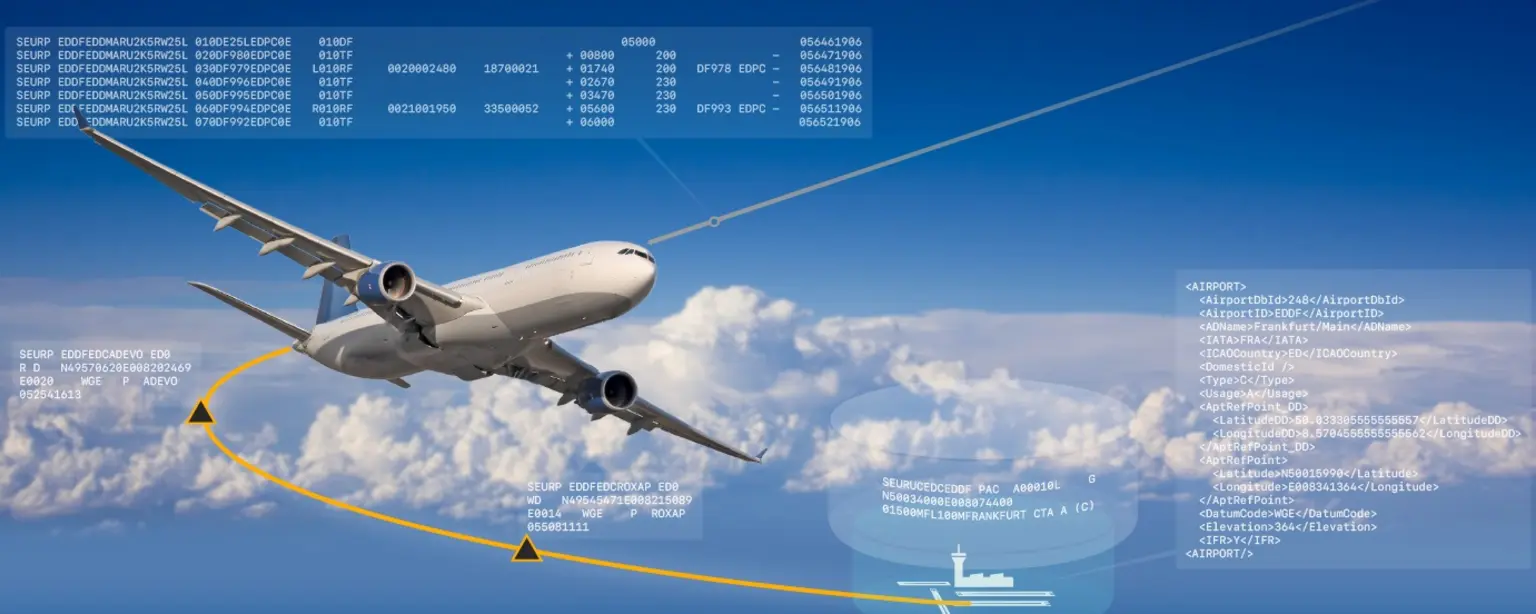

Robotic systems - Autonomous Racing at UVA (https://engineering.virginia.edu/research/autonomous-racing-uva):

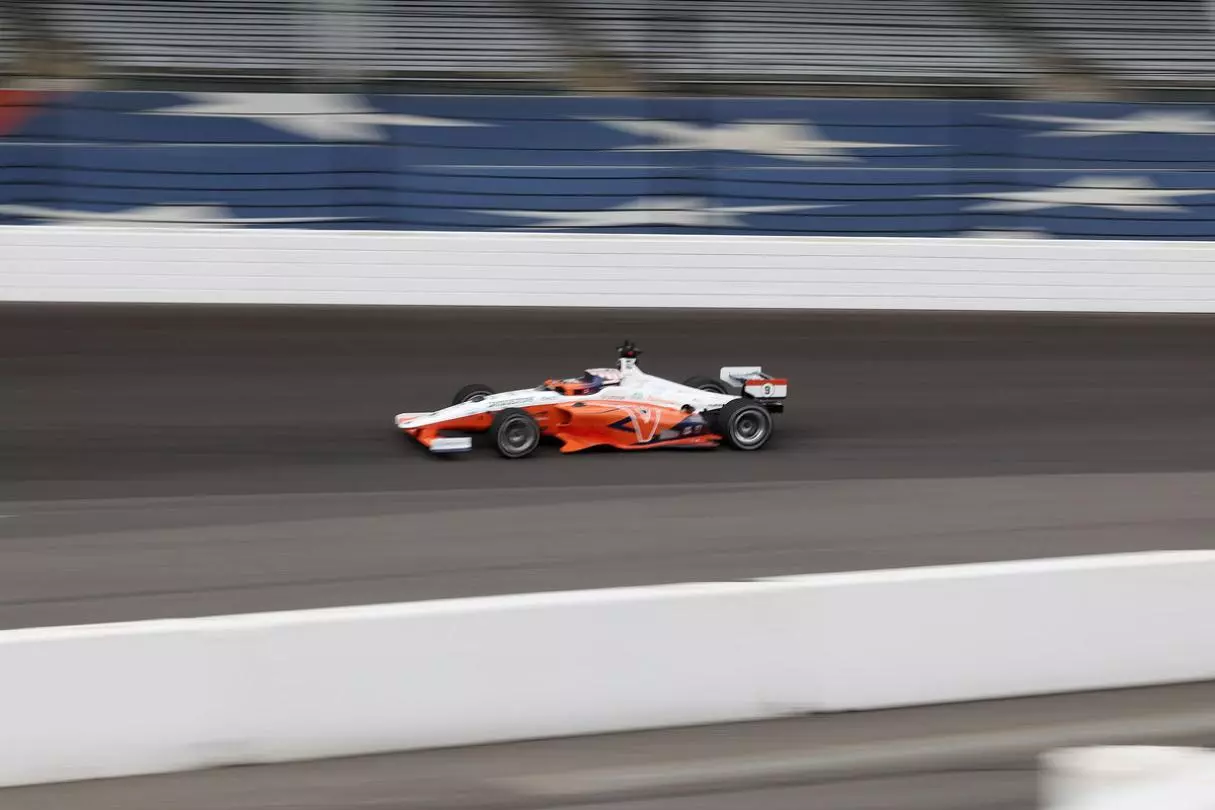

Navigation - Google map:

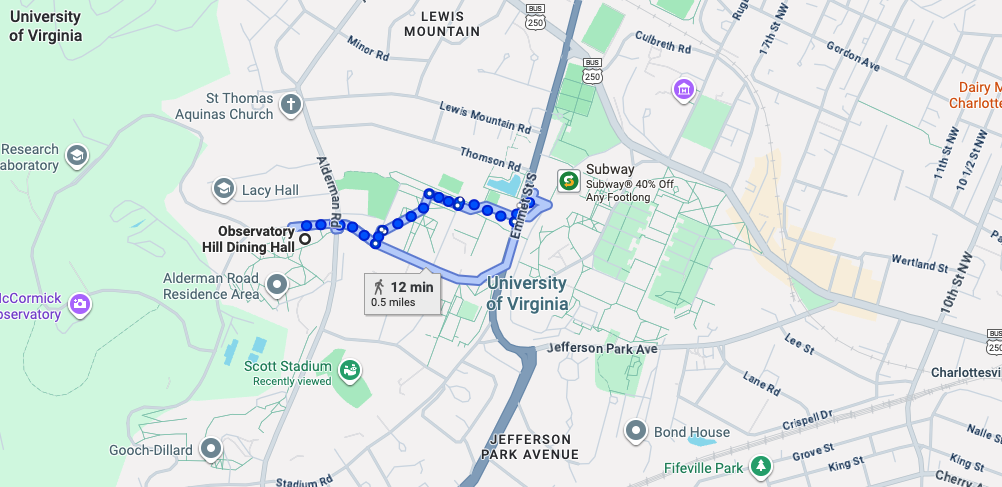

**Is there an app for that? **For many common computational tasks, we can rely on off-the-shelf software to achieve our needs.

- Word processing and presentation construction

- Mechanical or electronic design

- Web browsing

- etc.

For other tasks, we need customized software (code).

**What is code? **A computer code is a set of instructions, usually too difficult to carry out by hand.

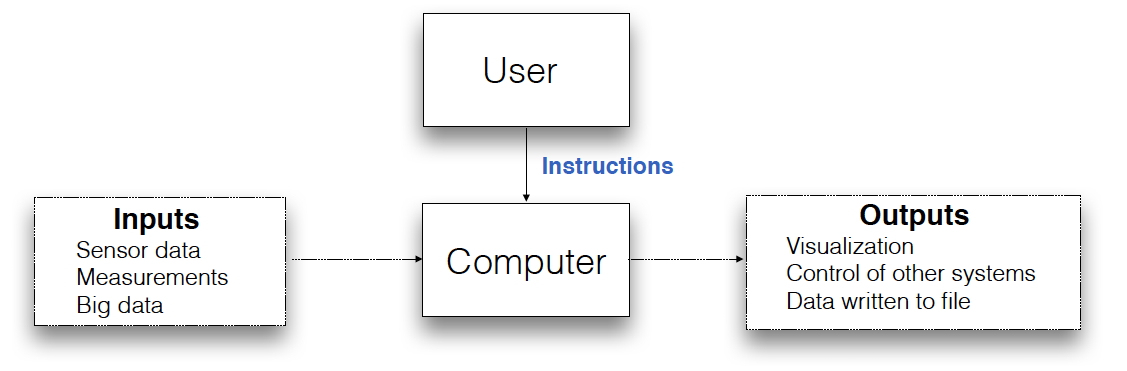

**Do you speak machine? **The computer’s CPU relies on very basic instructions to perform tasks on smallest units of data: Machine language. Writing a program in machine language would be tedious and is usually unnecessary. Instead, we rely on high-level languages to express the instructions.

How does high-level code get translated into machine-level instructions? Two principal ways:

- A compiled language

- An interpreted language

### **Compiled vs Interpreted**

In a compiled language, the instructions in the code are first compiled and linked into an ‘executable’.

- The compiler translates user code into machine language. Specific to machine.

- Compiler can optimize the order of instructions, making code run faster.

- Examples: C, C++, Fortran.

In an interpreted language, the instructions run a sequence of precompiled commands.

- There is no compilation step (and thus, no optimization). Code is generally slower.

- Examples: MATLAB, Python, Excel formulas, macros in various software.

Requirements of a program include:

- **Reliability**: Does it do what it is supposed to do?

- **Robustness**: Can it gracefully handle problematic inputs?

- **Usability**: Does it have a clear interface with the user?

- **Readability**: Can someone else figure out what it does? Is it well organized and well commented?

- **Efficiency**: Does it perform its task without consuming unnecessary resources (time, memory, etc.)?

The programming process include:

- Describe the objective(s) clearly

- Express the underlying model to achieve objective

- Develop algorithm(s) to solve the model equations

- Break down the algorithm into simple tasks

- Formulate tasks as pseudo-code

- Translate pseudo-code into actual code

- Debug the code

- Make code run more efficiently!

## Getting Acquainted with MATLAB

What is MATLAB?

- MATLAB = MATrix LABoratory

- MathWorks (the developers of MATLAB): “MATLAB® is a high-level language and interactive environment for numerical computation, visualization, and programming.” 

- Provides toolboxes and packages for a wide range of problems including image processing, biomedicine, statistics, etc.

- Interpreted language (not a compiled language) 

MATLAB Interface:

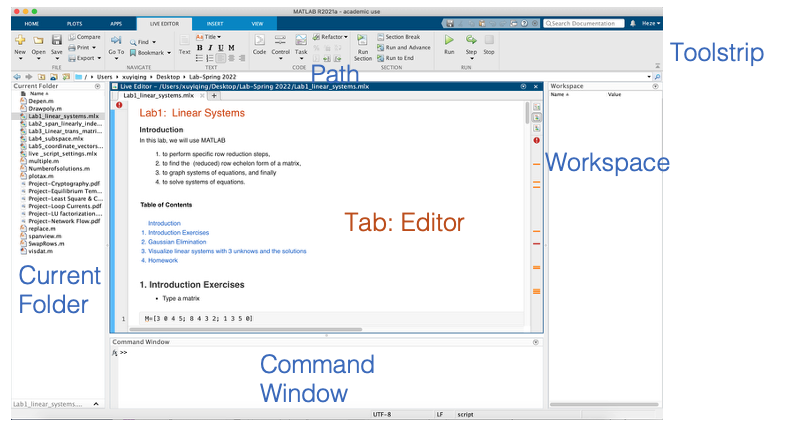

Note: 

- Current Folder - directory contents of the current path

- Command Window - allows single line execution of commands

- Workspace - displays current variables stored in memory.

- Command History - shows most recent commands executed using the command line.

- Toolstrip - menus for opening/saving scripts, importing data, viewing documentation, etc.

You can use MATLAB other than standalone version:

- MATLAB online: [https://](https://www.mathworks.com/products/matlab-online.html)[www.mathworks.com](https://www.mathworks.com/products/matlab-online.html)[/products/](https://www.mathworks.com/products/matlab-online.html)[matlab-online.html](https://www.mathworks.com/products/matlab-online.html)

- UVA remote desktop: [https://in.virginia.edu/remote-apps](https://in.virginia.edu/remote-apps)

### Command Line

We can use MATLAB as a simple calculator via the command line

5 + 3

This assigns the value '8' to the variable '`ans`', which is displayed in the workspace.

Now adding a semicolon to the end of the expression suppresses the display of '`ans`', but '`ans`' still stores the value '8'.

5 + 3;

MATLAB has built-in functions, constants and variables:

pi
cos(pi)
sin(pi)

Question: Why did that happen?

Answer: The function 'sin' can only be approximated (for example, by a Taylor series); pi is an irrational constant made of infinite digits, and computers cannot store infinitely long numbers.

### `Help`

To learn about MATLAB's built-in functions and variables, we can use the `help` feature.

help sin
help pi

Also, `doc` is a very useful command, which brings up the MATLAB documentation window.

### `Lookfor`

MATLAB's `lookfor` function searches through all help entries for a specific keyword

lookfor exponent

### Warnings/Errors

Error messages are extremely helpful for debugging, for example:

%coss(pi)

### Command Line History

Instead of retyping `cos(pi)` with correct spelling, we can use the up arrow key. The up arrow key browses through the history of previous commands, especially useful for lengthy commands. We can also select previous commands directly from the Command History window.

### Basic Data Types

- Numeric —> double (real), integer

- Logical (boolean)

- Character —> a string is a 1D array of characters

### Variables

Variables can be assigned a value without declaring a type. MATLAB implicitly converts a variable to a specific type. The assignment operator, '=', is used to give a variable a defined value.

% Below, the value 10 is assigned to variable 'distance'
distance = 10;

A variable of one type can be assigned data of another type:

distance = 10; % type double
distance = 'far'; % type char array (string)

In MATLAB, scalars are actually defined as matrices of size 1x1.

### Clear and Close Commands

% Clear command window
clc;
% Clear variable from the workspace
clear;
% Close figure
close;
% Clear (but do not close) current figure
clf;
% Typically scripts begin with
clc; close all; clearvars;

### MATLAB Scripting

**.m File**: A .m file is a MATLAB script file. For programs longer than a few lines, use of the command line becomes inefficient. To run an .m file saved as filename.m, simply type filename into the command line `>> filename` (can also press F5 or Run on the Toolstrip)

**.mlx File**: A .mlx file is a MATLAB live script file. They are interactive documents that combine MATLAB code with formatted text, equations, and images in a single environment. This file is a  MATLAB live script, and we will see more live scripts in the rest of this course!

### Comment

It is programmer-readable text embedded into the source code of a program, which is ignored by compilers and interpreters. Primary purpose is to make source code easier to understand. Comments help all users (including the original writer) to understand a script. It is good habit to use comments to concisely explain a piece of code, and typical convention is to place a comment prior to the code snippet it explains, for example:

% Calculate area of a circle
radius = 1;
area = pi*radius^2;

In MATLAB, comment lines begin with `%`. To comment multiple lines, use `%{…}%`. The first and final lines of a multi-line comment must be empty besides the delimiter, for example:

% This is a single line comment
%{
This is a multi-line comment
This text is green
%}

Double percent signs (`%%`) define a code section, which can be followed by an optional title, for example:

%% Calculate area of shapes
% Circle
areaCircle = pi*radius^2;
% Square
sideLength = 2;
areaSquare = sideLength^2;

Splitting code into sections allows the user to execute portions of code independently and keep code organized.

### Input (Taking Input from the Command Line)

Use MATLAB `input` function, for example

% The code fragment below requests user input and assigns the input to the variable 'firstName'
firstName = input('Enter your first name: ', 's');

### Printing

`fprintf` allows you to control the way data are printed to the command window. `fprintf(formatSpec,variable1,variable2,…,variableN)`, `formatSpec` is a string that determines how data are printed:

% The following code prints 'myNumber' in three different ways, skipping a line between each output
myNumber = 100;
fprintf('%d\n',myNumber);
fprintf('%e\n',myNumber);
fprintf('%f\n',myNumber);

`Field width` specifies the minimum number of characters to print. 

fprintf('%10f',myNumber) % Field width is entered before format specifier
fprintf('%6d',myNumber) % Prints myNumber with 3 empty spaces to the left of '100'

*Precision* specifies the number of digits to the right of the decimal point

fprintf('%10.6f',myNumber) % Precision is entered after field width
% Prints myNumber with 1 empty space and 1 zero after the decimal point. The decimal point counts as a space.
fprintf('%6.1f',myNumber)

`disp` also prints to the command window, but the output is not customizable.

### Condition Statement

if-else statement is used in situations where the decision to choose between a pair of alternative computations is based upon a single Boolean expression.

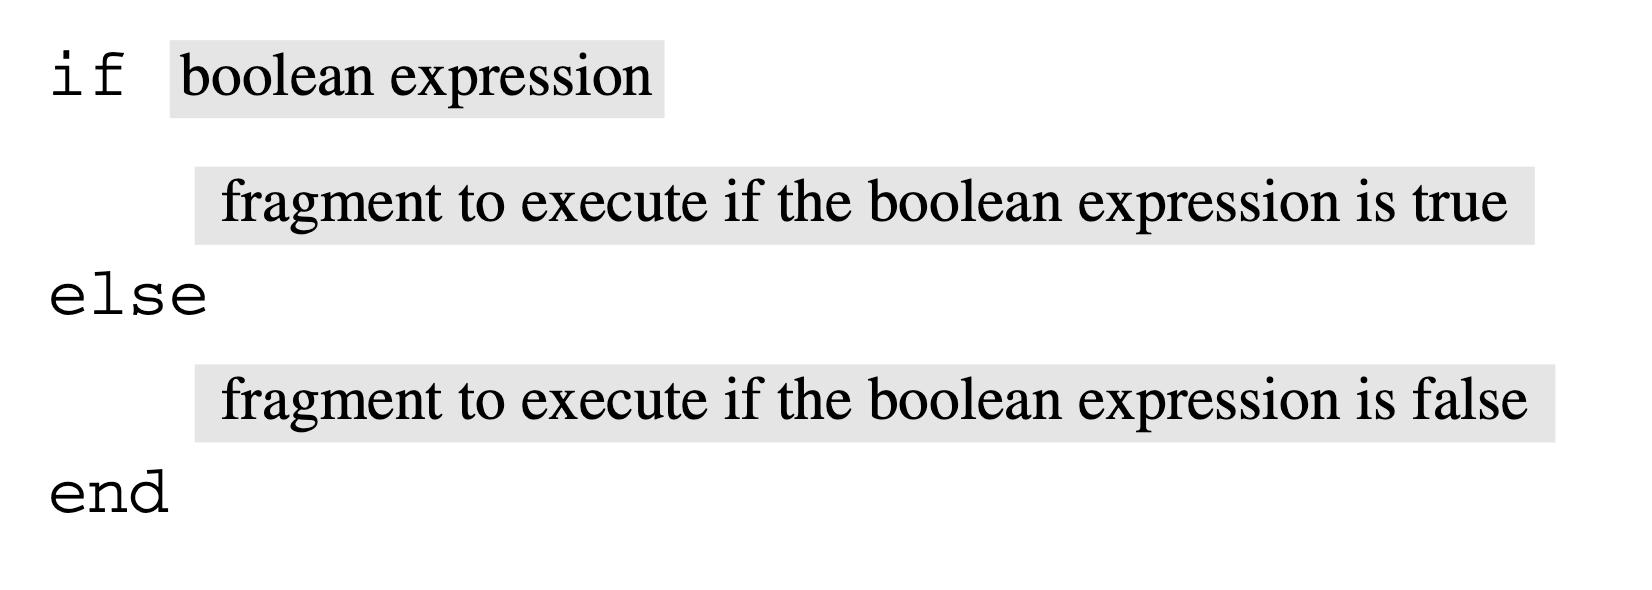

if small > big
    temp = small;
    small = big;
    big = temp;
end

Question: What does this section of code do?

### Iteration Statements

- for-loop is used in situations where a fragment needs to be repeatedly executed and the number of repetitions is known in advance.

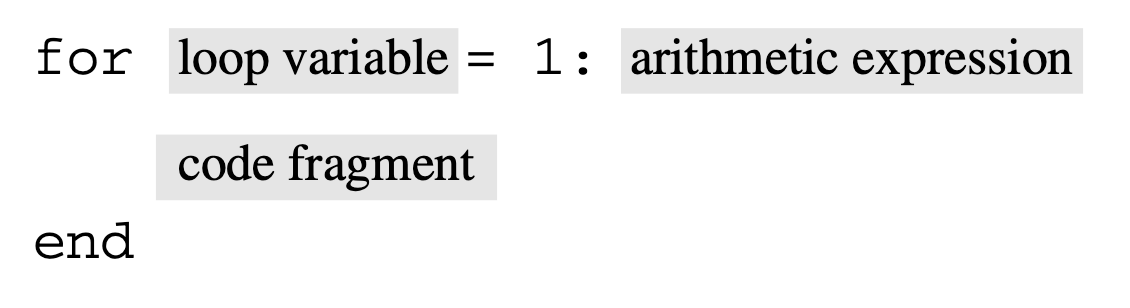

for k = 1:10
     fprintf('k = %d\n', k)
end

- while-loop is used in situations where a fragment needs to be repeatedly executed and the number of repetitions is not known in advance.

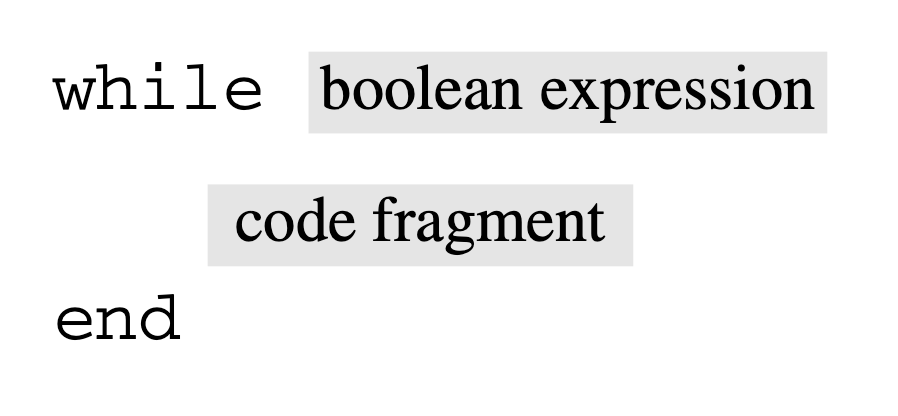

k =1; n =10;
while k <= n
    fprintf('k = %d\n', k)
    k = k + 1;
end